# Chest Scan Image Pre-Processing

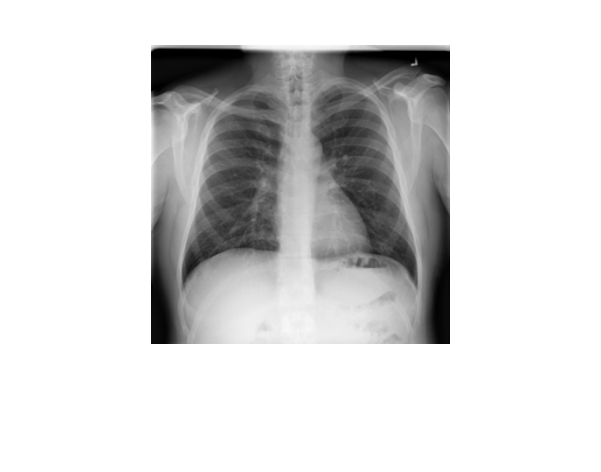

% Class - normal images
num_images = 10192; % number of images in dataset
normal_img = zeros((299*299),num_images);   % Initialize empty array
for i = 1:num_images
    filename = sprintf('./data/normal/Normal-%i.png', i);
    img = (imread(filename));
    normal_img(:,i) = double(reshape(img,[],1));    % reshapes image as column vector
end                                         % and adds it to normal_img
labels(1:num_images,1) = "normal";
imshow(img);    % test

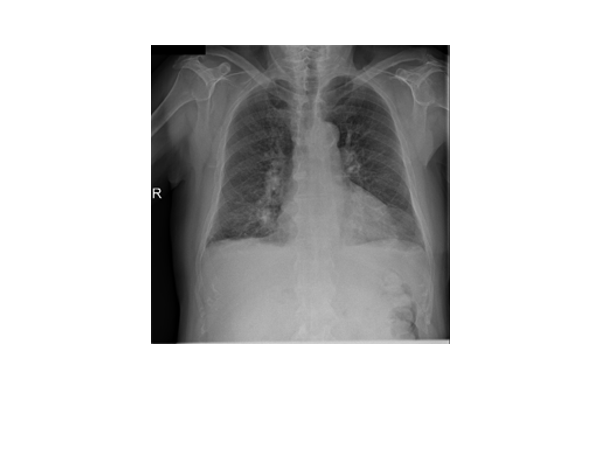

% Class - COVID (tbd)
num_images2 = 3615; % number of images in dataset
cov_img = zeros((299*299),num_images2);  % Initialize empty array
for i = 1:num_images2
    filename = sprintf('./data/COVID/COVID-%i.png', i);
    img = (imread(filename));
    cov_img(:,i) = double(reshape(img,[],1));       % reshapes image as column vector
end                                      % and adds it to cov_img
labels(num_images+1:num_images2+num_images,1) = "COVID";
imshow(img);    % test